## MULTI-HH TRAIN EXPERIMENT

In this notebook we will explore the training method of the multiHH class. 

**CLEANING AND FOLDERS**

%First let's clean everything and add needed folders
clc
clear
close all

addpath(genpath('extended/Domains/JSSP')); % Adds JSSP functionality
addpath(genpath('extended/Utils')); % Adds assorted utilities

**LOADING FILES**

%Loading sets of instances
load('instances_adv1.mat')
load('instances_adv2.mat')
load('instances_adv1_adv2_comb.mat')

%Loading HHs
load('FM_HH1_multi.mat')
load('FM_HH2_multi.mat')
load('FM_HH3_multi.mat')

%Loading SHHs
load('FM_SHH1.mat')
load('FM_SHH2.mat')
load('FM_SHH3.mat')
load('FM_SHH4.mat')
load('FM_SHH5.mat')
load('FM_CHH1.mat')

**RANDOM SHH VS TRAINED SHH **

%CREATING RANDOM SHH
%Hyper-Parameters 
props = struct('nbLayers',2,'selectedSolvers',1:3,...
 'nbRules',3,'innerHHs',[FM_HH1_multi FM_HH2_multi FM_HH3_multi],'selectedFeatures', [1 2 3 4 5]);

%Random Seed
rng(1)

warning('off')
%Creating SHH
randSHH=ruleBasedSelectionHHMulti(props);

Let's start by solving only 4 instances

%SOLVING INSTANCES
%solving 4 instances wit the random SHH 
instances_4={instances_comb{[1 31 61 91]}};
%Solving 4 instances with random SHH
solvedInstances_instances_4_randSHH=randSHH.solveInstanceSet(instances_4);

for i=1:length(instances_4)
    solvedInstances_instances_4_randSHH_makespans(i)=solvedInstances_instances_4_randSHH{i}.solution.makespan;
end 

Creatimg another SHH for training 

%CREATING ANOTHER SHH 
%Hyper-Parameters 
props = struct('nbLayers',2,'selectedSolvers',1:3,...
 'nbRules',3,'innerHHs',[FM_HH1_multi FM_HH2_multi FM_HH3_multi],'selectedFeatures', [1 2 3 4 5]);

%Random Seed
rng(2)

warning('off')
%Creating SHH
trainedSHH=ruleBasedSelectionHHMulti(props);

Training with the 4 selected instances (one of each kind)

%TRAINING THE SHH 
%setting the training instances
trainedSHH.trainingInstances={instances_comb{[1 31 61 91]}};

%parameters of training 
properties = struct('verboseMode', true, ...
                        'maxIter', 100, 'maxStagIter', 10);

%start training                    
trainedSHH.train('UPSO', properties)


[  09:22:59] UPSO2 starts...
         ... Inputs and outputs checked!
         ... Parameters initialised:

           visualMode: 0
          verboseMode: 1
       populationSize: 15
              maxIter: 100
          maxStagIter: 100
             selfConf: 2
           globalConf: 2.5000
          unifyFactor: 0.2500
      numberVariables: 18
    simpleConstraints: 1
             knownMin: -Inf
              stagTol: 0.1000
              funcTol: 1.0000e-03
               solTol: 1.0000e-06
         fitnessLimit: 1.0000e-06
          kappaFactor: 1
            phiFactor: 4.5000
       initialVelMode: 'rand'

         ... Neighbours established
         ... Population positions randomly initialised
         ... Population velocities randomly initialised
         ... Population initialised
         ... Search space adjusted
         ... Particular best fitness values determined

[Step     1] Global best fitness updated: 140.6
         ... Initialisation completed!

[Step     2] Glob

ans =     0.7214
    0.2493
    0.4902
    0.3505
    0.2875
    0.4435
    0.7407
    0.6788
    0.3236
    0.5625


Solving the same four instances to compare it with the random model

%SOLVING INSTANCES
%solving 4 instances wit the trained SHH 
instances_4={instances_comb{[1 31 61 91]}};
%Solving 4 instances with random SHH
solvedInstances_instances_4_trainedSHH=trainedSHH.solveInstanceSet(instances_4);

for i=1:length(instances_4)
    solvedInstances_instances_4_trainedSHH_makespans(i)=solvedInstances_instances_4_trainedSHH{i}.solution.makespan;
end 

VISUALIZATION: PlotZones and Makespan Violins

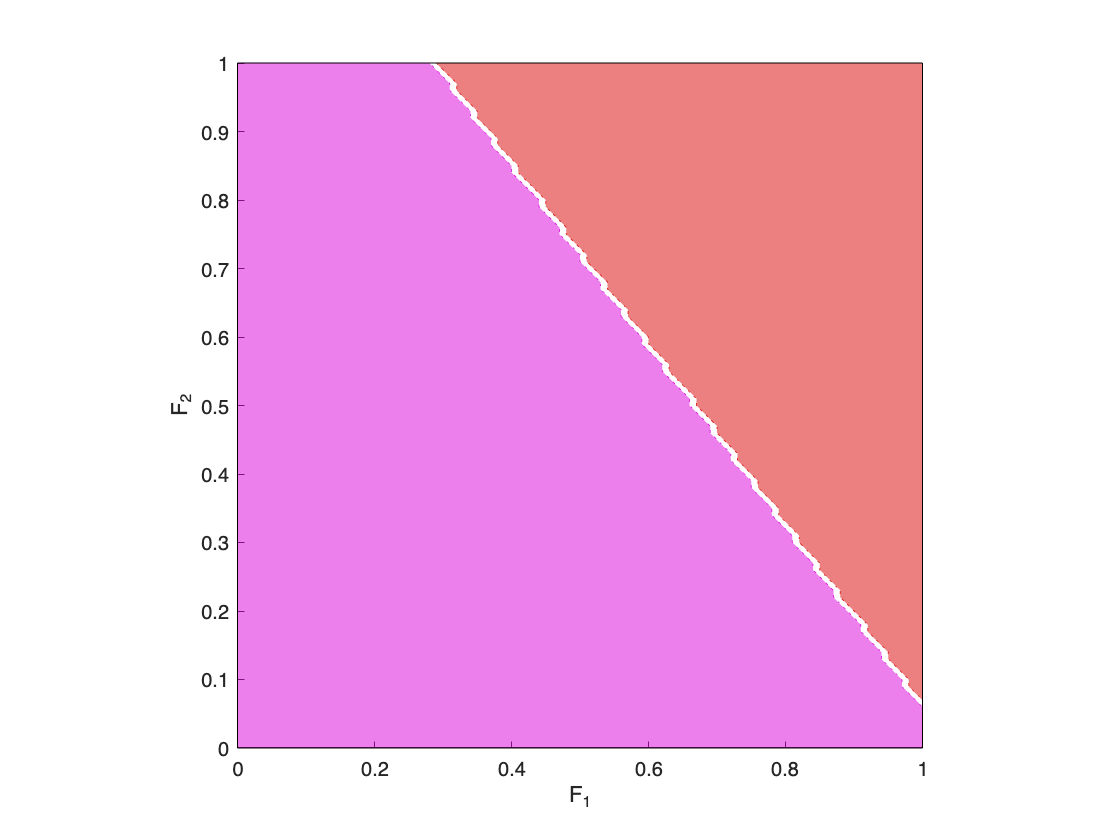

ans =     0.3291       NaN    0.6615


%VISUALIZATION 

randSHH.plotZones

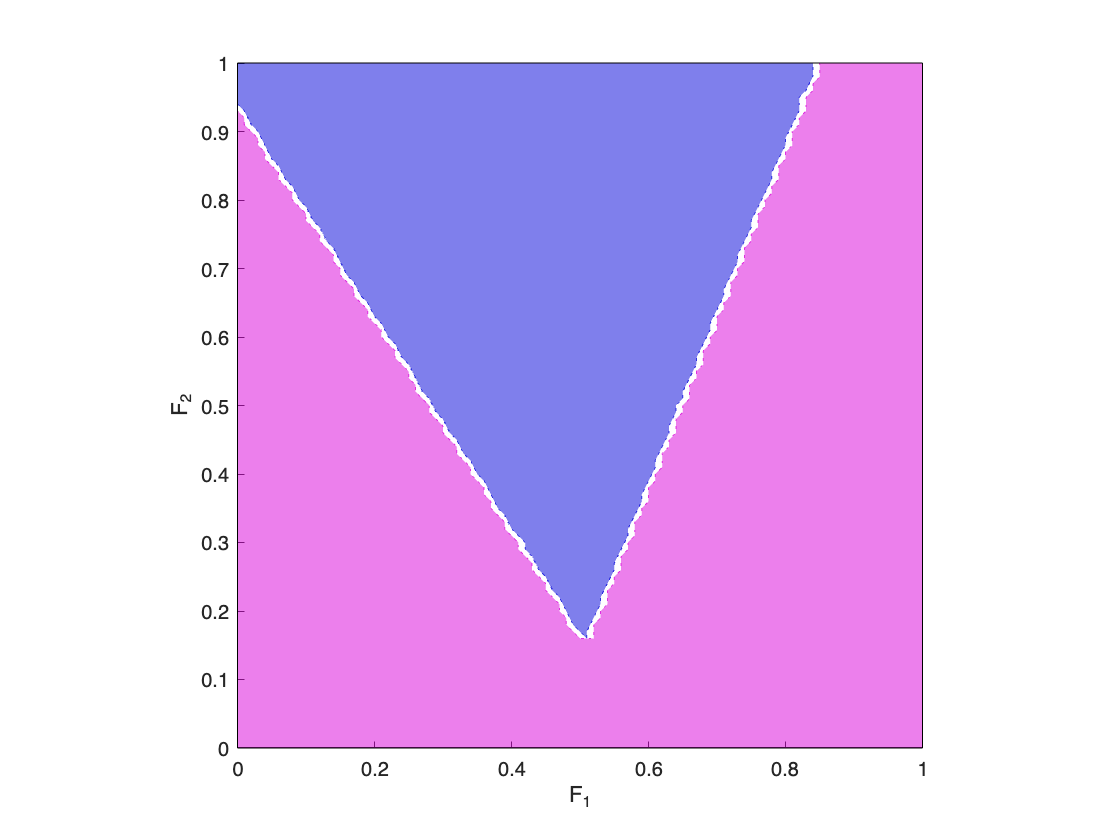

ans =        NaN    0.3702    0.6164


trainedSHH.plotZones

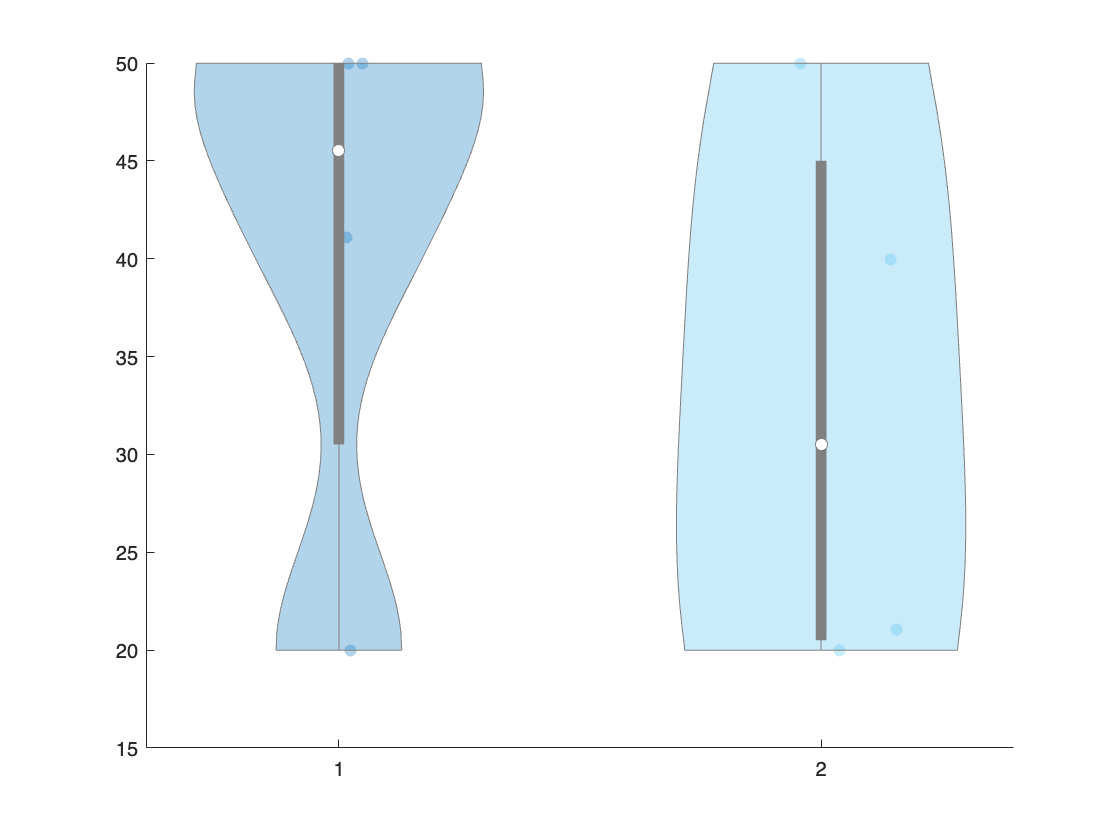

ans =   1×2 Violin array with properties:

    ScatterPlot
    ViolinPlot
    BoxPlot
    WhiskerPlot
    MedianPlot
    NotchPlots
    MeanPlot
    ViolinColor
    ViolinAlpha
    EdgeColor
    BoxColor
    BoxWidth
    MedianColor
    ShowData
    ShowNotches
    ShowMean


%Creating setup for violin plot
ViolinMatrix=[solvedInstances_instances_4_randSHH_makespans' solvedInstances_instances_4_trainedSHH_makespans'];
%plotting
figure
violinplot(ViolinMatrix)

Evidently the trained SHH (right violing) obtained better results.  

**NOW LET'S USE THE WHOLE INSTANCES_COMB **

First let's solve instances_comb with randSHH 

%SOLVING INSTANCES
%solving instances_comb with the random SHH 
solvedInstances_instances_comb_randSHH=randSHH.solveInstanceSet(instances_comb);

for i=1:length(instances_comb)
    solvedInstances_instances_comb_randSHH_makespans(i)=solvedInstances_instances_comb_randSHH{i}.solution.makespan;
end 

Now, let' solve instances_comb with trainedSHH (trained with 4 instances)

%SOLVING INSTANCES
%solving instances_comb with the trainedSHH 
solvedInstances_instances_comb_trainedSHH=trainedSHH.solveInstanceSet(instances_comb);

for i=1:length(instances_comb)
    solvedInstances_instances_comb_trainedSHH_makespans(i)=solvedInstances_instances_comb_trainedSHH{i}.solution.makespan;
end 

Visualization of the solved instance set instances_comb, let see if the trained SHH achieves generalization

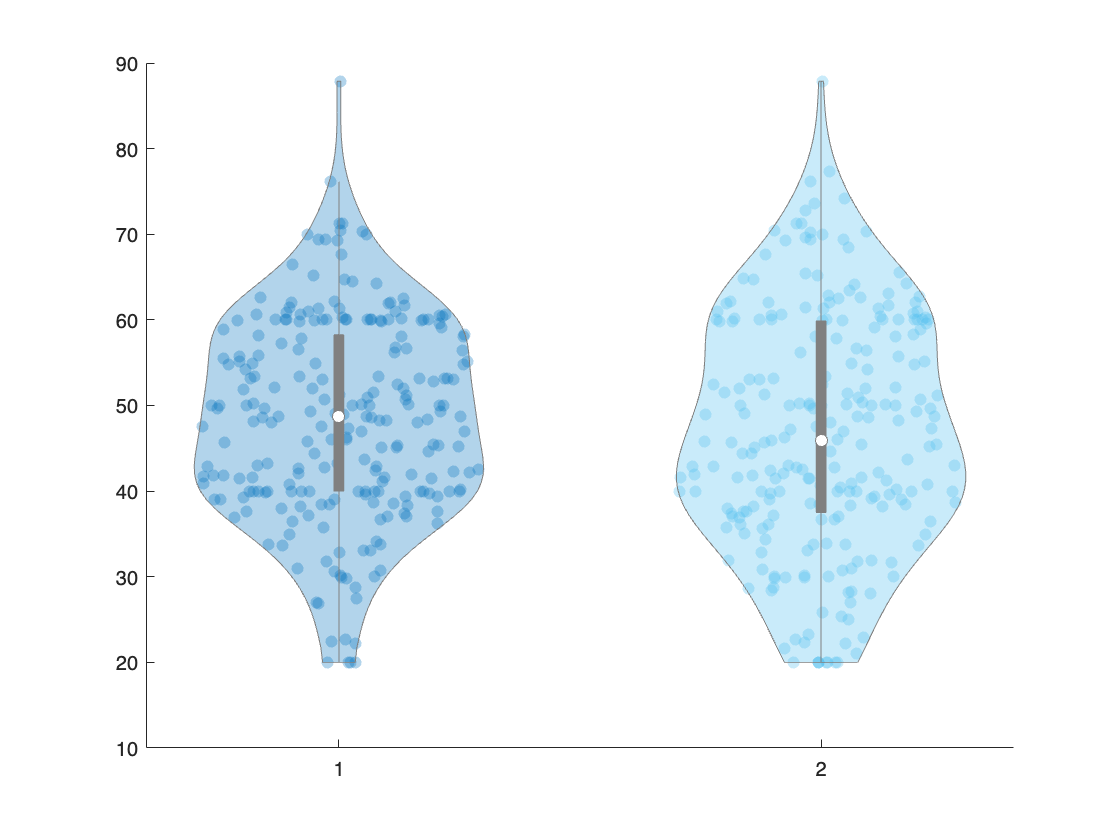

ans =   1×2 Violin array with properties:

    ScatterPlot
    ViolinPlot
    BoxPlot
    WhiskerPlot
    MedianPlot
    NotchPlots
    MeanPlot
    ViolinColor
    ViolinAlpha
    EdgeColor
    BoxColor
    BoxWidth
    MedianColor
    ShowData
    ShowNotches
    ShowMean


%Creating setup for violin plot
ViolinMatrix=[solvedInstances_instances_comb_randSHH_makespans' solvedInstances_instances_comb_trainedSHH_makespans'];
%plotting
figure
violinplot(ViolinMatrix)

Still better than the random one, but not a great difference. 

**Now, let's train a SHH with the whole instances_comb **

%CREATING ANOTHER SHH 
%Hyper-Parameters 
props = struct('nbLayers',2,'selectedSolvers',1:3,...
 'nbRules',3,'innerHHs',[FM_HH1_multi FM_HH2_multi FM_HH3_multi],'selectedFeatures', [1 2 3 4 5]);

%Random Seed
rng(1)

warning('off')
%Creating SHH
trainedSHH_2=ruleBasedSelectionHHMulti(props);

Training with instances_comb

%TRAINING THE SHH_2 
%setting the training instances
trainedSHH_2.trainingInstances=instances_comb;

%parameters of training 
properties = struct('verboseMode', true, ...
                        'maxIter', 100, 'maxStagIter', 10);

%start training                    
trainedSHH_2.train('UPSO', properties)


[  10:34:18] UPSO2 starts...
         ... Inputs and outputs checked!
         ... Parameters initialised:

           visualMode: 0
          verboseMode: 1
       populationSize: 15
              maxIter: 100
          maxStagIter: 100
             selfConf: 2
           globalConf: 2.5000
          unifyFactor: 0.2500
      numberVariables: 18
    simpleConstraints: 1
             knownMin: -Inf
              stagTol: 0.1000
              funcTol: 1.0000e-03
               solTol: 1.0000e-06
         fitnessLimit: 1.0000e-06
          kappaFactor: 1
            phiFactor: 4.5000
       initialVelMode: 'rand'

         ... Neighbours established
         ... Population positions randomly initialised
         ... Population velocities randomly initialised
         ... Population initialised
         ... Search space adjusted
         ... Particular best fitness values determined

[Step     1] Global best fitness updated: 1.158e+04
         ... Initialisation completed!

[Step     2] 

ans =     0.0354
    0.3474
    0.6240
    0.6253
    0.3921
    0.4824
    0.5621
    0.6364
    0.9977
    1.0000


save('trainedSHH_2','trainedSHH_2')

Now, let' solve instances_comb with trainedSHH_2

%SOLVING INSTANCES
%solving instances_comb with the trainedSHH 
solvedInstances_instances_comb_trainedSHH_2=trainedSHH_2.solveInstanceSet(instances_comb);

for i=1:length(instances_comb)
    solvedInstances_instances_comb_trainedSHH_2_makespans(i)=solvedInstances_instances_comb_trainedSHH_2{i}.solution.makespan;
end 

Visualization of the solved instance set instances_comb, let see if the trained SHH achieves generalization

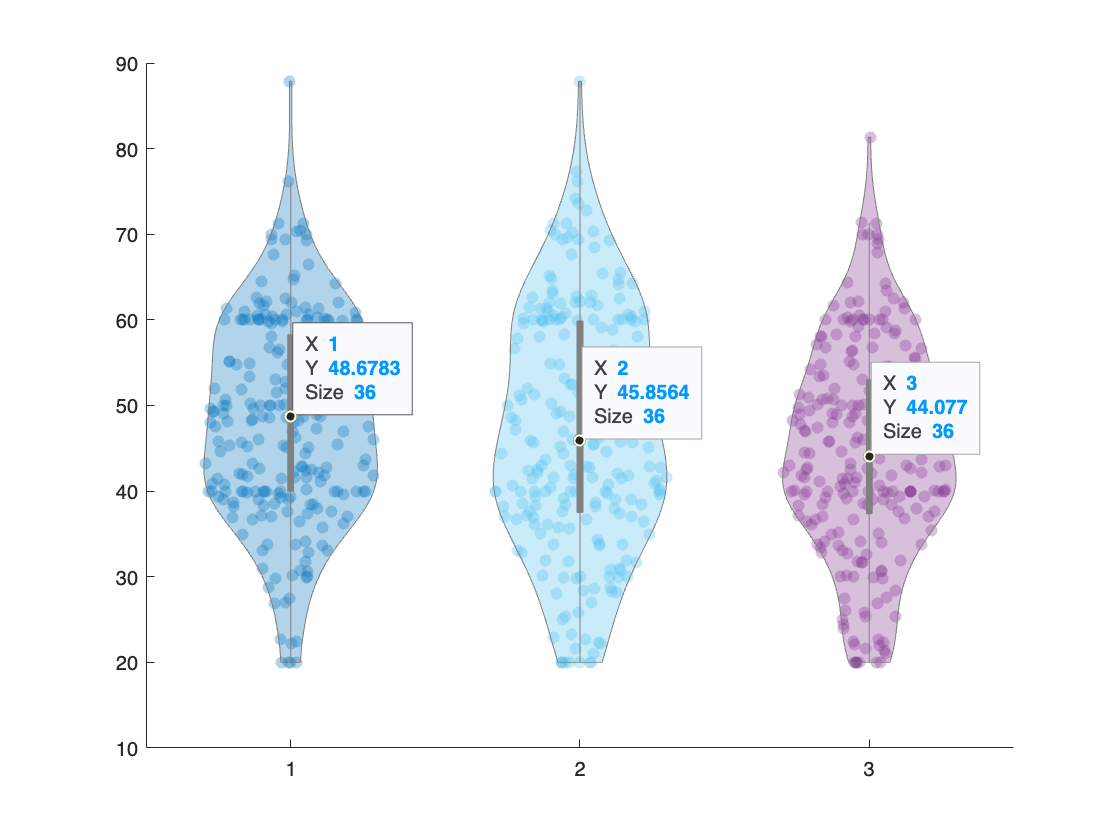

ans =   1×3 Violin array with properties:

    ScatterPlot
    ViolinPlot
    BoxPlot
    WhiskerPlot
    MedianPlot
    NotchPlots
    MeanPlot
    ViolinColor
    ViolinAlpha
    EdgeColor
    BoxColor
    BoxWidth
    MedianColor
    ShowData
    ShowNotches
    ShowMean


%Creating setup for violin plot
ViolinMatrix=[solvedInstances_instances_comb_randSHH_makespans' solvedInstances_instances_comb_trainedSHH_makespans' solvedInstances_instances_comb_trainedSHH_2_makespans'];
%plotting
figure
violinplot(ViolinMatrix)

There is not a lot of difference between the trained models, maybe the solver themselves are not enough. 

**Now let's create another SHH, trained with instances_comb, but less features **

%CREATING ANOTHER SHH WITH 2 FEAUTRES
%Hyper-Parameters 
props = struct('nbLayers',2,'selectedSolvers',1:3,...
 'nbRules',3,'innerHHs',[FM_HH1_multi FM_HH2_multi FM_HH3_multi],'selectedFeatures', [1 2]);

%Random Seed
rng(1)

warning('off')
%Creating SHH
trainedSHH_3=ruleBasedSelectionHHMulti(props);

Training with instances_comb

%TRAINING THE SHH_3 
%setting the training instances
trainedSHH_3.trainingInstances=instances_comb;

%parameters of training 
properties = struct('verboseMode', true, ...
                        'maxIter', 100, 'maxStagIter', 10);

%start training                    
trainedSHH_3.train('UPSO', properties)


[  08:48:21] UPSO2 starts...
         ... Inputs and outputs checked!
         ... Parameters initialised:

           visualMode: 0
          verboseMode: 1
       populationSize: 15
              maxIter: 100
          maxStagIter: 100
             selfConf: 2
           globalConf: 2.5000
          unifyFactor: 0.2500
      numberVariables: 9
    simpleConstraints: 1
             knownMin: -Inf
              stagTol: 0.1000
              funcTol: 1.0000e-03
               solTol: 1.0000e-06
         fitnessLimit: 1.0000e-06
          kappaFactor: 1
            phiFactor: 4.5000
       initialVelMode: 'rand'

         ... Neighbours established
         ... Population positions randomly initialised
         ... Population velocities randomly initialised
         ... Population initialised
         ... Search space adjusted
         ... Particular best fitness values determined

[Step     1] Global best fitness updated: 1.149e+04
         ... Initialisation completed!

[Step     2] G

ans =          0
    0.0481
    0.1318
    0.3639
    0.6664
    0.3413
    3.0000
    2.7721
    2.2386


save('trainedSHH_3','trainedSHH_3')

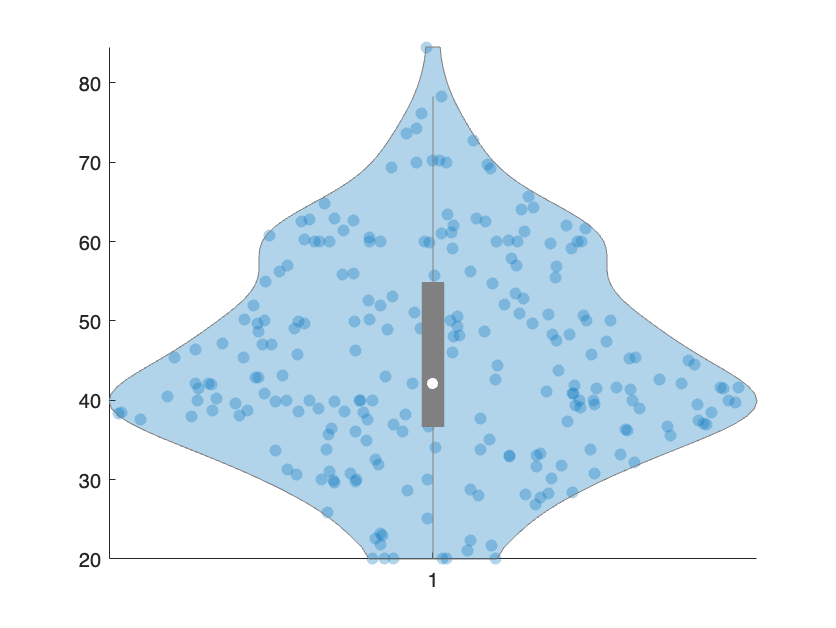

ans =   Violin with properties:

    ScatterPlot: [1×1 Scatter]
     ViolinPlot: [1×1 Patch]
        BoxPlot: [1×1 Patch]
    WhiskerPlot: [1×1 Line]
     MedianPlot: [1×1 Scatter]
     NotchPlots: [1×2 Scatter]
       MeanPlot: [1×1 Line]
    ViolinColor: [0 0.4470 0.7410]
    ViolinAlpha: 0.3000
      EdgeColor: [0.5000 0.5000 0.5000]
       BoxColor: [0.5000 0.5000 0.5000]
       BoxWidth: 0.0200
    MedianColor: [1 1 1]
       ShowData: 1
    ShowNotches: 0
       ShowMean: 0


%SOLVING INSTANCES
%solving instances_comb with the trainedSHH 
solvedInstances_instances_comb_trainedSHH_3=trainedSHH_3.solveInstanceSet(instances_comb);

for i=1:length(instances_comb)
    solvedInstances_instances_comb_trainedSHH_3_makespans(i)=solvedInstances_instances_comb_trainedSHH_3{i}.solution.makespan;
end 

%Creating setup for violin plot
ViolinMatrix=[solvedInstances_instances_comb_trainedSHH_3_makespans'];
%plotting
figure
violinplot(ViolinMatrix)

It does get better, meaning that with a smaller space of models (because we only used 2 features), its easier to find a good one. For 5 features theres is maybe a better solution but it would take more than 100 steps to find it. 

**CHH MODELS **

Let's try with FM_CHH1 which has access to SHH5 and LPA

%setting the training instances
FM_CHH1.trainingInstances={instances_comb{[1 31 61 91]}};

%parameters of training 
properties = struct('verboseMode', true, ...
                        'maxIter', 100, 'maxStagIter', 10);

%start training                    
FM_CHH1.train('UPSO', properties)


[  08:52:38] UPSO2 starts...
         ... Inputs and outputs checked!
         ... Parameters initialised:

           visualMode: 0
          verboseMode: 1
       populationSize: 15
              maxIter: 100
          maxStagIter: 100
             selfConf: 2
           globalConf: 2.5000
          unifyFactor: 0.2500
      numberVariables: 6
    simpleConstraints: 1
             knownMin: -Inf
              stagTol: 0.1000
              funcTol: 1.0000e-03
               solTol: 1.0000e-06
         fitnessLimit: 1.0000e-06
          kappaFactor: 1
            phiFactor: 4.5000
       initialVelMode: 'rand'

         ... Neighbours established
         ... Population positions randomly initialised
         ... Population velocities randomly initialised
         ... Population initialised
         ... Search space adjusted
         ... Particular best fitness values determined

[Step     1] Global best fitness updated: 171
         ... Initialisation completed!

[Step     2] Global 

ans =     0.6765
    0.6080
    0.8578
         0
    1.1025
    1.6096


The training seems to be working, as the makespan accumulate improved. It did not improved a lot but it could be due to the limitations of the model, as it only has 2 rules and 1 feature. 

%Trained model
FM_CHH1.value

ans =     0.6765    0.8578    1.0000
    0.6080         0    2.0000


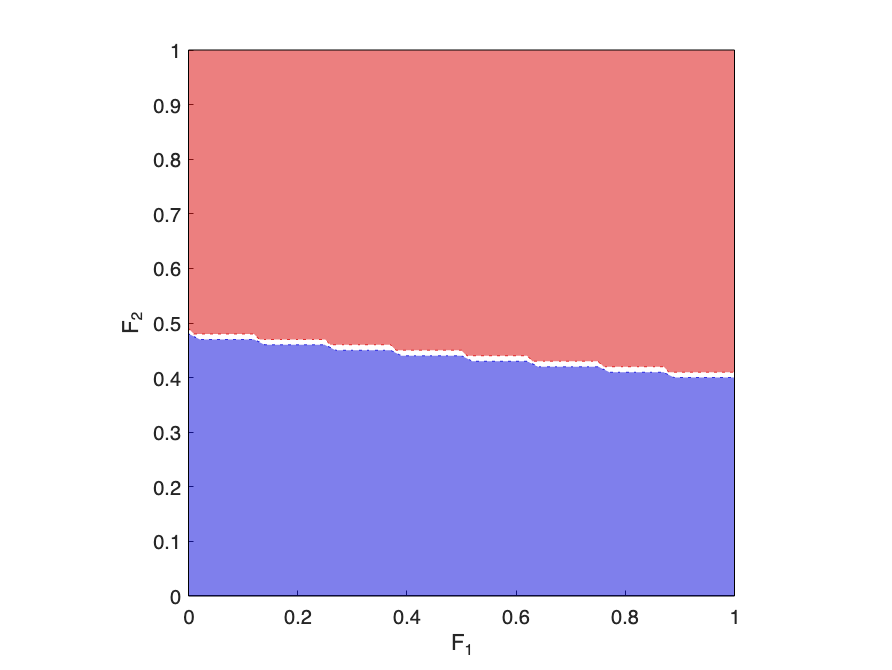

ans =     0.5548    0.4356


%Visualization of the rules
FM_CHH1.plotZones

**TRAINING A NEW CHH MODEL **

%Loadig SHHs
load('FM_SHH1.mat')
load('FM_SHH2.mat')
load('FM_SHH3.mat')
load('FM_SHH4.mat')
load('FM_SHH5.mat')

rng(1)
%Creating a new CHH model with access to SHH1-5, 5 rules and 5 features
props = struct('nbLayers',3,'selectedSolvers',1:5,...
                 'nbRules',5,'innerHHs',[FM_SHH1 FM_SHH2 FM_SHH3 FM_SHH4 FM_SHH5],'selectedFeatures', [1 2 3 4 5]);
FirstTrainedCHH=ruleBasedSelectionHHMulti(props)

FirstTrainedCHH = Warning: The hyper-heuristic has not been trained yet! 
> In selectionHH/disp (line 439)
In matlab.internal.editor/VariableOutputPackager/isolatedDisplaying
In matlab.internal.editor/VariableOutputPackager/getStringFromVar
In matlab.internal.editor/VariableOutputPackager/getTruncatedStringFromVar
In matlab.internal.editor/VariableOutputPackager/packageVarOther
In matlab.internal.editor/VariableOutputPackager/packageOutput
In 

Let's force the model to choose all 5 SHHs 

%changing the model 
FirstTrainedCHH.value(1,end)=1;
FirstTrainedCHH.value(2,end)=2;
FirstTrainedCHH.value(3,end)=3;
FirstTrainedCHH.value(4,end)=4;
FirstTrainedCHH.value(5,end)=5

FirstTrainedCHH = Warning: The hyper-heuristic has not been trained yet! 
> In selectionHH/disp (line 439)
In matlab.internal.editor/VariableOutputPackager/isolatedDisplaying
In matlab.internal.editor/VariableOutputPackager/getStringFromVar
In matlab.internal.editor/VariableOutputPackager/getTruncatedStringFromVar
In matlab.internal.editor/VariableOutputPackager/packageVarOther
In matlab.internal.editor/VariableOutputPackager/packageOutput
In 

Solving Instances_comb with the generated model 

%solving instances
solvedInstances_FirstTrainedCHH=FirstTrainedCHH.solveInstanceSet(instances_comb);

%Retrieving 
solvedInstances_FirstTrainedCHH_makespans=nan(1,size(solvedInstances_FirstTrainedCHH,2));

for x=1:length(solvedInstances_FirstTrainedCHH)
    solvedInstances_FirstTrainedCHH_makespans(x)=solvedInstances_FirstTrainedCHH{x}.solution.makespan;   
end


**TRAINING THE CHH model with 4 instances **

rng(1)
%setting the training instances
FirstTrainedCHH.trainingInstances={instances_comb{[1 31 61 91]}};

%parameters of training 
properties = struct('verboseMode', true, ...
                        'maxIter', 100, 'maxStagIter', 10);

%start training                    
FirstTrainedCHH.train('UPSO', properties)


[  08:53:49] UPSO2 starts...
         ... Inputs and outputs checked!
         ... Parameters initialised:

           visualMode: 0
          verboseMode: 1
       populationSize: 15
              maxIter: 100
          maxStagIter: 100
             selfConf: 2
           globalConf: 2.5000
          unifyFactor: 0.2500
      numberVariables: 30
    simpleConstraints: 1
             knownMin: -Inf
              stagTol: 0.1000
              funcTol: 1.0000e-03
               solTol: 1.0000e-06
         fitnessLimit: 1.0000e-06
          kappaFactor: 1
            phiFactor: 4.5000
       initialVelMode: 'rand'

         ... Neighbours established
         ... Population positions randomly initialised
         ... Population velocities randomly initialised
         ... Population initialised
         ... Search space adjusted
         ... Particular best fitness values determined

[Step     1] Global best fitness updated: 121
         ... Initialisation completed!

[Step     2] Global

ans =     0.4375
    0.6246
    0.8768
    0.5349
    0.0279
    0.5082
    0.6205
    0.5961
    0.6066
    0.7292


**TESTING THE TRAINED MODEL**

%solving instances
solvedInstances_FirstTrainedCHH_trained4=FirstTrainedCHH.solveInstanceSet(instances_comb);

%Retrieving 
solvedInstances_FirstTrainedCHH_makespans_trained4=nan(1,size(solvedInstances_FirstTrainedCHH,2));

for x=1:length(solvedInstances_FirstTrainedCHH_trained4)
    solvedInstances_FirstTrainedCHH_makespans_trained4(x)=solvedInstances_FirstTrainedCHH_trained4{x}.solution.makespan;   
end

**VISUALIZING BOTH RESULTS **

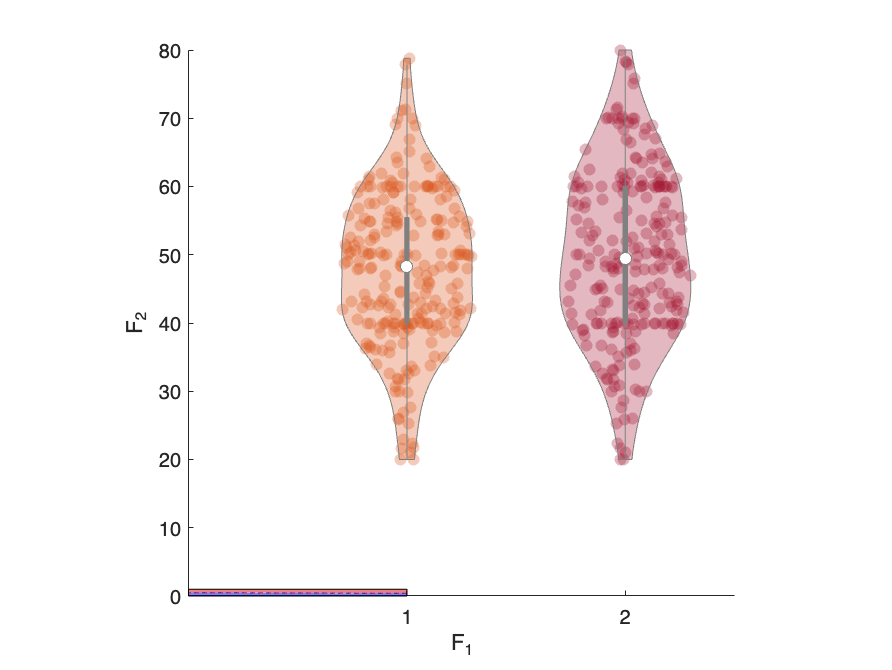

ans =   1×2 Violin array with properties:

    ScatterPlot
    ViolinPlot
    BoxPlot
    WhiskerPlot
    MedianPlot
    NotchPlots
    MeanPlot
    ViolinColor
    ViolinAlpha
    EdgeColor
    BoxColor
    BoxWidth
    MedianColor
    ShowData
    ShowNotches
    ShowMean


%Creating setup for violin plot
FirstTrainedCHH_makespansMatrix=[solvedInstances_FirstTrainedCHH_makespans' solvedInstances_FirstTrainedCHH_makespans_trained4'];
%plotting
violinplot(FirstTrainedCHH_makespansMatrix)

mean(FirstTrainedCHH_makespansMatrix)

ans =    47.7376   49.9977


It looks that the overfitting affected the performance of the trained CHH

**RE-TRAINING THE CHH MODEL WITH 20 INSTANCES **

rng(1)
%setting the training instances
FirstTrainedCHH.trainingInstances={instances_comb{[1:5 31:35 61:65 91:95]}};

%parameters of training 
properties = struct('verboseMode', true, ...
                        'maxIter', 100, 'maxStagIter', 10);

%start training                    
FirstTrainedCHH.train('UPSO', properties)


[  08:59:27] UPSO2 starts...
         ... Inputs and outputs checked!
         ... Parameters initialised:

           visualMode: 0
          verboseMode: 1
       populationSize: 15
              maxIter: 100
          maxStagIter: 100
             selfConf: 2
           globalConf: 2.5000
          unifyFactor: 0.2500
      numberVariables: 30
    simpleConstraints: 1
             knownMin: -Inf
              stagTol: 0.1000
              funcTol: 1.0000e-03
               solTol: 1.0000e-06
         fitnessLimit: 1.0000e-06
          kappaFactor: 1
            phiFactor: 4.5000
       initialVelMode: 'rand'

         ... Neighbours established
         ... Population positions randomly initialised
         ... Population velocities randomly initialised
         ... Population initialised
         ... Search space adjusted
         ... Particular best fitness values determined

[Step     1] Global best fitness updated: 859.7
         ... Initialisation completed!

[Step     2] Glob

ans =     0.7271
    0.8018
    0.0621
    0.3734
    0.5575
    0.0290
    0.3528
    0.7787
    0.0999
    0.9524


**TESTING THE TRAINED MODEL**

%solving instances
solvedInstances_FirstTrainedCHH_trained20=FirstTrainedCHH.solveInstanceSet(instances_comb);

%Retrieving 
solvedInstances_FirstTrainedCHH_makespans_trained20=nan(1,size(solvedInstances_FirstTrainedCHH,2));

for x=1:length(solvedInstances_FirstTrainedCHH_trained20)
    solvedInstances_FirstTrainedCHH_makespans_trained20(x)=solvedInstances_FirstTrainedCHH_trained20{x}.solution.makespan;   
end

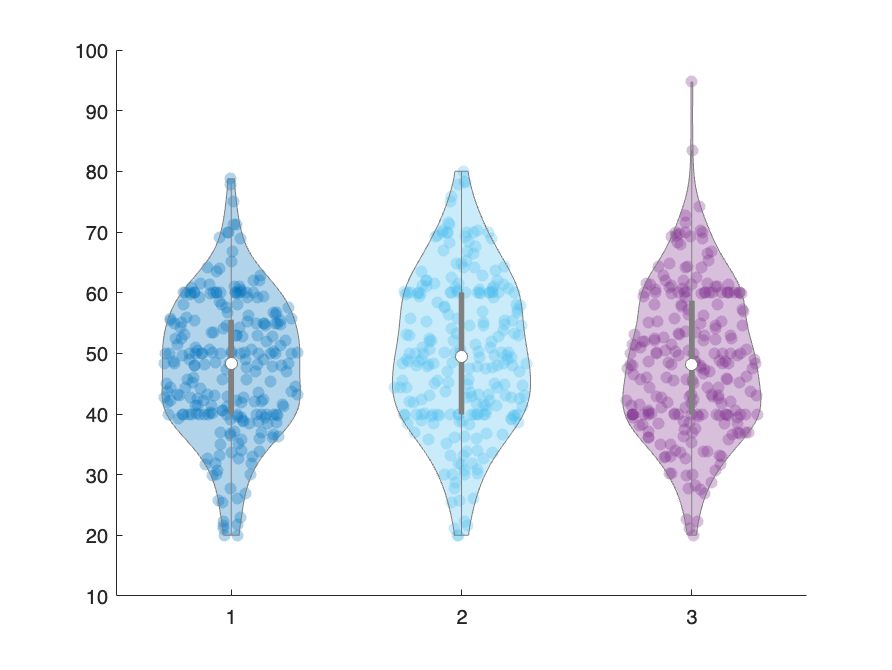

ans =   1×3 Violin array with properties:

    ScatterPlot
    ViolinPlot
    BoxPlot
    WhiskerPlot
    MedianPlot
    NotchPlots
    MeanPlot
    ViolinColor
    ViolinAlpha
    EdgeColor
    BoxColor
    BoxWidth
    MedianColor
    ShowData
    ShowNotches
    ShowMean


%Creating setup for violin plot
FirstTrainedCHH_makespansMatrix=[solvedInstances_FirstTrainedCHH_makespans' solvedInstances_FirstTrainedCHH_makespans_trained4' solvedInstances_FirstTrainedCHH_makespans_trained20'];
%plotting
figure
violinplot(FirstTrainedCHH_makespansMatrix)

mean(FirstTrainedCHH_makespansMatrix)

ans =    47.7376   49.9977   48.6412


FirstTrainedCHH.value

ans =     0.7271    0.0290    0.1429    0.6349    0.6083    5.0000
    0.8018    0.3528    0.9572    0.9972    0.4410    3.0000
    0.0621    0.7787    0.2971    0.7698    0.6304    5.0000
    0.3734    0.0999    0.0247    0.9283    0.3251    1.0000
    0.5575    0.9524    0.0711    0.0481    0.0018    4.0000


rng(1)
%Creating a new HH model with access to LPT,SPT,MPA,LPA, 4 rules, and 5
%features
fields=struct('nbRules',4,'selectedSolvers',[1 2 3 4],'selectedFeatures',[1 2 3 4 5]);
HH1=ruleBasedSelectionHH(fields)

HH1 = Warning: The hyper-heuristic has not been trained yet! 
> In selectionHH/disp (line 439)
In matlab.internal.editor/VariableOutputPackager/isolatedDisplaying
In matlab.internal.editor/VariableOutputPackager/getStringFromVar
In matlab.internal.editor/VariableOutputPackager/getTruncatedStringFromVar
In matlab.internal.editor/VariableOutputPackager/packageVarOther
In matlab.internal.editor/VariableOutputPackager/packageOutput
In <a href="matlab:matlab.internal.language.introspective.errorDocCallback('LiveEditorEvaluationHelperE1274958325', '/private/var/folders/j5/5pvt36fn4_5b3xbqy4wr8snm0000gn/T/Editor_jfpsx/LiveEditorEvaluationHelperE1274958325.m', 109)" style="font-wei

HH1.value(1,end)=1;
HH1.value(2,end)=2;
HH1.value(3,end)=3;
HH1.value(4,end)=4

HH1 = Warning: The hyper-heuristic has not been trained yet! 
> In selectionHH/disp (line 439)
In matlab.internal.editor/VariableOutputPackager/isolatedDisplaying
In matlab.internal.editor/VariableOutputPackager/getStringFromVar
In matlab.internal.editor/VariableOutputPackager/getTruncatedStringFromVar
In matlab.internal.editor/VariableOutputPackager/packageVarOther
In matlab.internal.editor/VariableOutputPackager/packageOutput 
Displaying information about the New HH:
	Target problem:      JSSP
	Type:                Rule-based
Training information:
	Method:     Undefined
	Number of instances: 0 (training) | 0 (testing)
	Parameters:
   NaN

	Performance achieved:	
	Time tak

%Solving instances_comb with the random HH1 model 
solvedInstances_HH1=HH1.solveInstanceSet(instances_comb);

solvedInstances_HH1 = 1×240 cell array
    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPIn


solvedInstances_HH1_makespans=nan(1,240); 

for x=1:length(solvedInstances_HH1)
    solvedInstances_HH1_makespans(x)=solvedInstances_HH1{x}.solution.makespan;
end 


**TRAINING HH1 WITH 4 INSTANCES**

rng(1)
%setting the training instances
HH1.trainingInstances={instances_comb{[1 31 61 91]}};

%parameters of training 
properties = struct('verboseMode', true, ...
                        'maxIter', 100, 'maxStagIter', 10);

%start training                    
HH1.train('UPSO', properties)


[  09:25:06] UPSO2 starts...
         ... Inputs and outputs checked!
         ... Parameters initialised:

           visualMode: 0
          verboseMode: 1
       populationSize: 15
              maxIter: 100
          maxStagIter: 100
             selfConf: 2
           globalConf: 2.5000
          unifyFactor: 0.2500
      numberVariables: 24
    simpleConstraints: 1
             knownMin: -Inf
              stagTol: 0.1000
              funcTol: 1.0000e-03
               solTol: 1.0000e-06
         fitnessLimit: 1.0000e-06
          kappaFactor: 1
            phiFactor: 4.5000
       initialVelMode: 'rand'

         ... Neighbours established
         ... Population positions randomly initialised
         ... Population velocities randomly initialised
         ... Population initialised
         ... Search space adjusted
         ... Particular best fitness values determined

[Step     1] Global best fitness updated: 140.8
         ... Initialisation completed!

[Step     2] Glob

ans =     0.3480
    0.1938
    0.5712
    0.6707
    0.2278
    0.3100
    0.7490
    0.5566
    0.1166
    0.8364


%Solving instances_comb with the trained4 HH1 model 
solvedInstances_HH1_trained4=HH1.solveInstanceSet(instances_comb);

solvedInstances_HH1_makespans_trained4=nan(1,240); 

for x=1:length(solvedInstances_HH1_trained4)
    solvedInstances_HH1_makespans_trained4(x)=solvedInstances_HH1_trained4{x}.solution.makespan;
end 

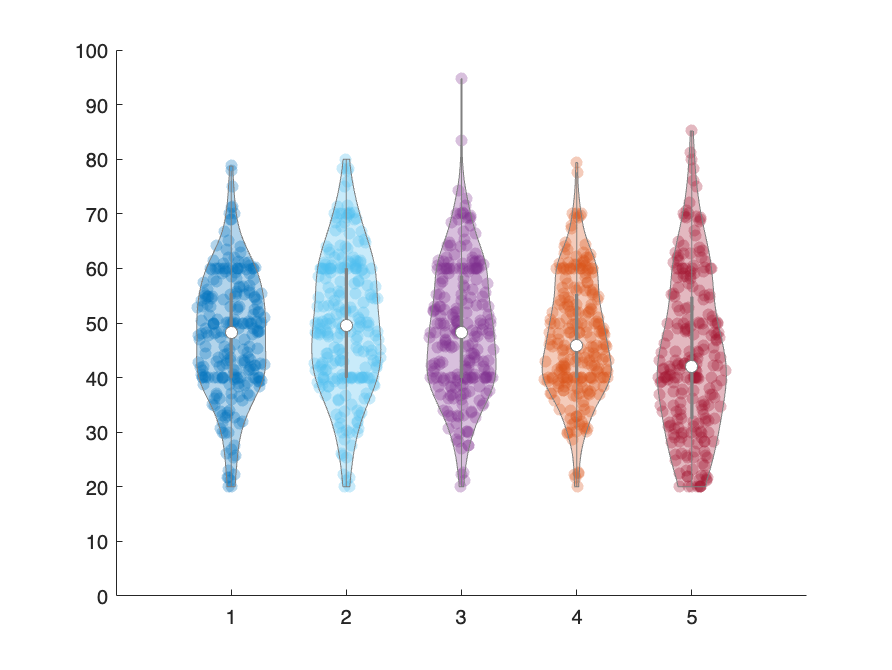

ans =   1×5 Violin array with properties:

    ScatterPlot
    ViolinPlot
    BoxPlot
    WhiskerPlot
    MedianPlot
    NotchPlots
    MeanPlot
    ViolinColor
    ViolinAlpha
    EdgeColor
    BoxColor
    BoxWidth
    MedianColor
    ShowData
    ShowNotches
    ShowMean


%Creating setup for violin plot
FirstTrainedCHH_makespansMatrix=[solvedInstances_FirstTrainedCHH_makespans' solvedInstances_FirstTrainedCHH_makespans_trained4' solvedInstances_FirstTrainedCHH_makespans_trained20' solvedInstances_HH1_makespans' solvedInstances_HH1_makespans_trained4'];
%plotting
figure
violinplot(FirstTrainedCHH_makespansMatrix)

With this we can conclude that the training method is working. The created HH works best because CHH might be biased towards only one heuristic. 